%双目
mode="mode4";
selectMode(mode,0);

clearvars -global
%双目
cam=struct('fx',718.856,'fy',718.856,'cx',607.1928,'cy',185.2157,'b',0.537165719);
nPose=10;
%生成一个相机圆轨迹
R=30;circleO=[0;0;0];
path='/media/zhijian/Document/grow/slam/slamDataSet/KITTI/data_odometry_poses/xyz.txt';
%path='F:\grow/slam/slamDataSet/KITTI/data_odometry_poses/xyz.txt';
%从数据集中生成线，其中包含了起始点和终止点世界坐标系坐标
%line_w=generateFromDateSet(path,3,cam);
[line_w point_w]=generateHouse(cam);

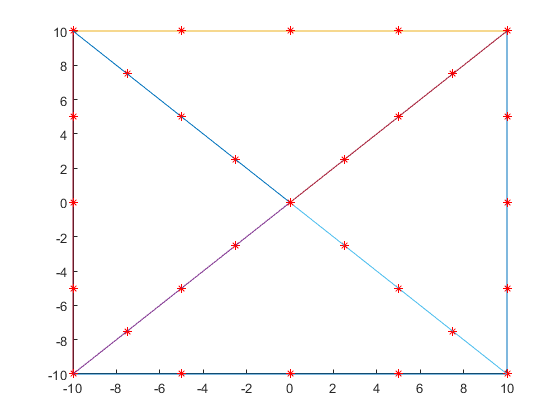

nLine=length(line_w);
nPoint=length(point_w);
figure;hold on
for i=1:length(line_w)
    line3(line_w{1,i}.sP,line_w{1,i}.eP);
end
plot3(point_w(1,:),point_w(2,:),point_w(3,:),'r*')

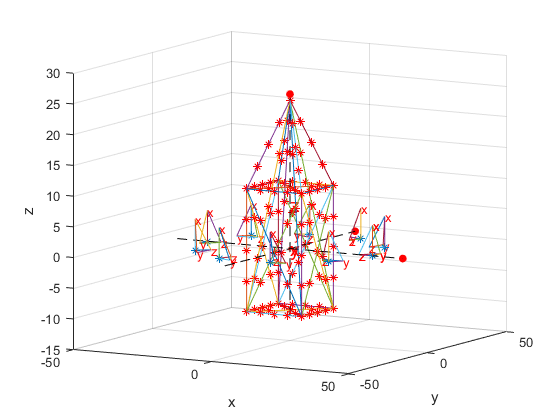

Twc=cell(1,nPose+1);Tcw=Twc;Tcp=cell(1,nPose);line_c=cell(nPose+1,nLine);Twc_=Twc;
%获得光心在世界坐标系下的坐标，以及每一帧的Twc,实际上生成了11个
[OpticCenter,Twc]=plotCamera(circleO,R,nPose);
for i=1:nPose+1
    Tcw{i}=Twc{i}^-1;
end
figureAxis();

%根据每一帧的Twc，求得每一帧与前一帧的相对位姿Tcur_pre
for i=1:nPose
    Tcp{i}=Twc{i+1}^-1*Twc{i};
end
%更新每一帧的观测，包括相机坐标系的坐标，像素坐标，视差
for i=1:nPose+1
    for j=1:nLine
        line_c{i,j}=updateLineByTwc(line_w{j},Twc{i},cam);
        %line_c{i,j}=addNoiseToLine(line_c{i,j},0.01,cam);
    end
    for n=1:nPoint
        point_c{i,n}=updatePointByTwc(point_w(:,n),Twc{i},cam);
        %line_c{i,j}=addNoiseToLine(line_c{i,j},0.01,cam);
    end
end

未定义与 'struct' 类型的输入参数相对应的运算符 '^'。

出错 pl_slam>updateLineByTwc (line 300)
Tcw=Twc^-1;

%构建共视关系
graph=zeros(1,nLine);
for i=1:nLine
    graph(1,i)=1;
end
%生成第一帧相机坐标系的随机线
iterTime=zeros(1,nPose);
i=1;
    Tcp_=disturbancePose('pose')*Tcp{i};
    %local BA lambda初始化
    lambda=0.00001;
    lambda_k=10.0;
    [H,g,e]=trackBA({point_c{i,:}},{point_c{i+1,:}},{line_c{i,:}},{line_c{i+1,:}},Tcp_,graph,cam);
    Hmax=0;
    for j=1:length(H)
        if abs(H(j,j))>Hmax
            Hmax=abs(H(j,j));
        end
    end
    lambda=lambda*Hmax;
    H=H+lambda*sqrt(abs(diag(diag(H))));
    delta_Tcp=linsolve(H,g);
    %更新位姿和地图点
    Tcp_=expse3(delta_Tcp)*Tcp_;
    [~,~,bestErr(i)]=trackBA({point_c{i,:}},{point_c{i+1,:}},{line_c{i,:}},{line_c{i+1,:}},Tcp{i},graph,cam);
    while abs(e)>bestErr(i) && iterTime(i)<10 %&& norm(delta_Tcp)>0.00001
        iterTime(i)=iterTime(i)+1;
        err_pre=e;
        [H,g,e]=trackBA({point_c{i,:}},{point_c{i+1,:}},{line_c{i,:}},{line_c{i+1,:}},Tcp_,graph,cam);
        H=H;%+lambda*sqrt(abs(diag(diag(H))));
        delta_Tcp=linsolve(H,g);
        %更新位姿和地图点
        if e>err_pre
            lambda=lambda/lambda_k;
        else
            minErr(i)=e;
            lambda=lambda*lambda_k;
            Tcp_=expse3(delta_Tcp)*Tcp_;
        end
    end
e
Tcp_-Tcp{1}
bestErr


%构建共视关系
graph=zeros(1,nLine);
for i=1:nLine
    graph(1,i)=1;
end
%生成第一帧相机坐标系的随机线
iterTime=zeros(1,nPose);
for i=1:length(Tcp)
    Tcp_=disturbancePose('pose')*Tcp{i};
    %local BA lambda初始化
    lambda=0.00001;
    lambda_k=10.0;
    [H,g,e]=trackBA({point_c{i,:}},{point_c{i+1,:}},{line_c{i,:}},{line_c{i+1,:}},Tcp_,graph,cam);
    Hmax=0;
    for j=1:length(H)
        if abs(H(j,j))>Hmax
            Hmax=abs(H(j,j));
        end
    end
    lambda=lambda*Hmax;
    H=H;%+lambda*(abs(diag(diag(H))));
    delta_Tcp=linsolve(H,g);
    %更新位姿和地图点
    Tcp_=expse3(delta_Tcp)*Tcp_;
    [~,~,bestErr(i)]=trackBA({point_c{i,:}},{point_c{i+1,:}},{line_c{i,:}},{line_c{i+1,:}},Tcp{i},graph,cam);
    while abs(e)>bestErr(i) && iterTime(i)<10 %&& norm(delta_Tcp)>0.00001
        iterTime(i)=iterTime(i)+1;
        err_pre=e;
        [H,g,e]=trackBA({point_c{i,:}},{point_c{i+1,:}},{line_c{i,:}},{line_c{i+1,:}},Tcp_,graph,cam);
        H=H;%+lambda*sqrt(abs(diag(diag(H))));
        delta_Tcp=linsolve(H,g);
        %更新位姿和地图点
        if e>err_pre
            lambda=lambda/lambda_k;
        else
            minErr(i)=e;
            lambda=lambda*lambda_k;
            Tcp_=expse3(delta_Tcp)*Tcp_;
        end
    end
    Twc_{1}=Twc{1};
    Twc_{i+1}=Twc_{i}/Tcp_;
end
iterTime=mean(iterTime)
meanErr=mean(minErr)
bestErr=mean(bestErr)
%iterTimeAvr=mean(iterTime)
compareTraj(Twc_,Twc);


%局部地图优化
%设定初值
x=zeros(6*nPose+4*nLine,1);
xop=zeros(6*nPose+4*nLine,1);
for i=1:nPose
    poseIdx=(i-1)*6+1;
    x(poseIdx:poseIdx+5)=logSE3(disturbancePose('pose')*Tcw{i});
    xop(poseIdx:poseIdx+5)=logSE3(Tcw{i});
end
for i=1:nLine
    lineIdx=6*nPose+(i-1)*6+1;
    x(lineIdx:lineIdx+5)=[[eye(3) zeros(3,1)]*disturbancePose('point')*...
    [line_w{i}.sP;1];[eye(3) zeros(3,1)]*disturbancePose('point')*[line_w{i}.eP;1]];
    xop(lineIdx:lineIdx+5)=[line_w{i}.sP;line_w{i}.eP];
end
%构建共视图
for i=1:nPose
    for j=1:nLine
        graph(i,j)=1;
    end
end
%local BA lambda初始化
lambda=4;
lambda_k=1.05;
[H, g, bestErr]=localBA(xop,nPose,nLine,line_c,graph,cam);
Hmax=0;
for i=1:length(H)
    if abs(H(i,i))>Hmax
        Hmax=abs(H(i,i));
    end
end
%lambda=lambda*Hmax;
H=H+lambda*(abs(diag(diag(H))));
iterTime=0;   
e=inf;
err_pre=bestErr;
delta_x=inf;
while  abs(e)>1e-5 && iterTime<1000 && norm(delta_x)>0.00001
    iterTime=iterTime+1;
    err_pre=e;
    [H, g, e]=localBA(x,nPose,nLine,line_c,graph,cam);
    H=H+lambda*(abs(diag(diag(H))));
    delta_x=linsolve(H,g);
%     length(H(1:60,1:60))-rank(H(1:60,1:60))
%     length(H)-rank(H)
    %更新位姿和地图点
    if e>err_pre
        lambda=lambda/lambda_k;
    else
        lambda=lambda*lambda_k;
        x=updateX(x,delta_x,nPose,nLine);
    end
    record(iterTime,:)=[lambda e];
end
bestErr
iterTime

e
norm(delta_x)
for i=1:nPose
    poseIdx=(i-1)*6+1;
    Tcw{i}=expse3(x(poseIdx:poseIdx+5));
    Twc_{i}=Tcw{i}^-1;
end
err=compareTraj(Twc_,{Twc{1:nPose-1}});

function [line] = generateFromDateSet(path,num,cam)
xyd=textread(path);
[m,n]=size(xyd);
k=0;
line=cell(1,10);
for i=1:round(m/num):m
    for j=1:n
        if mod(j,6)==1 && j<=n-5 && min(xyd(i,j:j+5))>0 && cam.b*cam.fx/xyd(i,j+2)<40 && cam.b*cam.fx/xyd(i,j+5)<40
            k=k+1;
            sp0=xyd(i,j);
            sp1=xyd(i,j+1);
            sdisp=xyd(i,j+2);
            ep0=xyd(i,j+3);
            ep1=xyd(i,j+4);
            edisp=xyd(i,j+5);
            p1=[sp0;sp1;1];
            p2=[ep0;ep1;1];
            line{k}=struct('sP',p1,'eP',p2,'L',0,'orth',0);
            line{k}.sP(3)=cam.b*cam.fx/sdisp;
            line{k}.sP(1)=(p1(1)-cam.cx)*line{k}.sP(3)/cam.fx;
            line{k}.sP(2)=(p1(2)-cam.cy)*line{k}.sP(3)/cam.fy;
            line{k}.eP(3)=cam.b*cam.fx/edisp;
            line{k}.eP(1)=(p2(1)-cam.cx)*line{k}.eP(3)/cam.fx;
            line{k}.eP(2)=(p2(2)-cam.cy)*line{k}.eP(3)/cam.fy;
            [line{k}.L,line{k}.orth]=point2line(line{k}.sP,line{k}.eP);
            v1=[0;0;1];
            v2=[0;1;0];
            Rwc=Tfromv1v2(v1,v2);
            line{k}.sP=Rwc*line{k}.sP+[0;-20;-2.5];
            line{k}.eP=Rwc*line{k}.eP+[0;-20;-2.5];
        end
    end
end
end

%小房子
function [line p] = generateHouse(cam)
line=cell(1,10);
p11=[10;10;10];p21=[10;-10;10];p31=[-10;-10;10];p41=[-10;10;10];
p12=[10;10;-10];p22=[10;-10;-10];p32=[-10;-10;-10];p42=[-10;10;-10];p00=[0;0;10+10*sqrt(2)];
p=[p11 p21 p31 p41 p12 p22 p32 p42 p00];
comb=combntns([1:9],2);
k=0;
for i=1:length(comb)
    if norm(cross(p(:,comb(i,1)),p(:,comb(i,2))))>1e-5
        k=k+1;
        line{k}=struct('sP',p11,'eP',p21,'L',0,'orth',0);
        line{k}.sP=p(:,comb(i,1));
        line{k}.eP=p(:,comb(i,2));
        [line{k}.L,line{k}.orth]=point2line(line{k}.sP,line{k}.eP);
        p=[p (p(:,comb(i,1))+p(:,comb(i,2)))/2 0.25*p(:,comb(i,1))+0.75*p(:,comb(i,2)) 0.75*p(:,comb(i,1))+0.25*p(:,comb(i,2))];
    end
end
end

%%获取相机轨迹
function [Pw ,Twc] = plotCamera(circleO,R,num,lgth)
if nargin==3
    lgth=5;
end
t=0:360/num:360;
Pw=[R*cosd(t);R*sind(t);zeros(1,length(t))]+repmat(circleO,1,length(t));
[~,n]=size(Pw);
Twc=cell(1,num+1);
for i=1:n
    if i<2
        v1=[0;0;1];
        v2=circleO-Pw(:,i);
        Rwc=Tfromv1v2(v1,v2);
        twc=Pw(:,i);
        Twc{i}=[Rwc twc;0 0 0 1];
    else
        v1=circleO-Pw(:,i-1);
        v2=circleO-Pw(:,i);
        Rwc=Tfromv1v2(v1,v2);
        %twc=Twc{i-1}*[(Pw(:,i)-Pw(:,i-1));1];
        twc=zeros(3,1);
        Twc{i}=[Rwc twc(1:3);0 0 0 1]*Twc{i-1};
    end
    p0=Twc{i}*[0;0;0;1];
    px=Twc{i}*[lgth;0;0;1];
    py=Twc{i}*[0;lgth;0;1];
    pz=Twc{i}*[0;0;lgth;1];
    line3(p0,px);
    line3(p0,py);
    line3(p0,pz);
    line3(px,py);
    line3(px,pz);
    line3(py,pz);
    text(pz(1),pz(2),pz(3),'z','Color','red','FontSize',10)
    text(py(1),py(2),py(3),'y','Color','red','FontSize',10)
    text(px(1),px(2),px(3),'x','Color','red','FontSize',10)
    %plotPlane3(px,py,pz,'r');
end
    plot3(Pw(1,:),Pw(2,:),Pw(3,:),'*')
end
%根据线的世界坐标和Twc获得每一帧的相机坐标系的参数
function [line_c,point_c] = updateLineByTwc(line_w,point_w,Twc,cam)
Tcw=Twc^-1;
Rcw=Tcw(1:3,1:3);
tcw=Tcw(1:3,4);
line_c=struct('sp',zeros(3,1),'ep',zeros(3,1),'sP',zeros(3,1),'eP',zeros(3,1),'sdisp',0,'edisp',0,'L',0,'orth',0);

line_c.sP=Rcw*line_w.sP+tcw;
line_c.eP=Rcw*line_w.eP+tcw;

line_c.sp=projectMono(line_c.sP,cam);
line_c.ep=projectMono(line_c.eP,cam);

line_c.sdisp=cam.b*cam.fx/line_c.sP(3);
line_c.edisp=cam.b*cam.fx/line_c.eP(3);
[line_c.L,line_c.orth]=point2line(line_c.sP,line_c.eP);

point_c=struct('P',zeros(3,1),'p',zeros(3,1),'disp',0);
point_c.P=Rcw*point_w+tcw;
point_c.p=projectMono(point_c.P,cam);
point_c.disp=cam.b*cam.fx/point_c.P(3);

end

function [point_c] = updatePointByTwc(point_w,Twc,cam)
Tcw=Twc^-1;
Rcw=Tcw(1:3,1:3);
tcw=Tcw(1:3,4);

point_c=struct('P',zeros(3,1),'p',zeros(3,1),'disp',0);
point_c.P=Rcw*point_w+tcw;
point_c.p=projectMono(point_c.P,cam);
point_c.disp=cam.b*cam.fx/point_c.P(3);

end

function [line]=addNoiseToLine(line,std,cam)
    line.sp=line.sp+[std*randn(2,1);0];
    line.ep=line.ep+[std*randn(2,1);0];
    line.sdisp=line.sdisp+std*randn(1);
    line.edisp=line.edisp+std*randn(1);
    line.sP(3)=cam.b*cam.fx/line.sdisp;
    line.sP(1)=(line.sp(1)-cam.cx)*line.sP(3)/cam.fx;
    line.sP(2)=(line.sp(2)-cam.cy)*line.sP(3)/cam.fy;
    line.eP(3)=cam.b*cam.fx/line.edisp;
    line.eP(1)=(line.ep(1)-cam.cx)*line.eP(3)/cam.fx;
    line.eP(2)=(line.ep(2)-cam.cy)*line.eP(3)/cam.fy;
end

function [err]=compareTraj(Twc_,Twc)
n=length(Twc);
twc=zeros(3,1);
twc_=zeros(3,1);
err=zeros(1,n);
for i=1:n
    twc(:,i)=Twc{i}(1:3,4);
    twc_(:,i)=Twc_{i}(1:3,4);
    Rwc{i}=Twc{i}(1:3,1:3);
    Rwc_{i}=Twc_{i}(1:3,1:3);
end
for i=1:n
err(i)=norm(twc(:,i)-twc_(:,i));
errAngle(i)=norm(logSO3(Rwc{i})-logSO3(Rwc_{i}));
end
err=sqrt(mean(err.^2));
errAngle=sqrt(mean(errAngle.^2));
figure
plot3(twc_(1,:),twc_(2,:),twc_(3,:))
hold on
plot3(twc(1,:),twc(2,:),twc(3,:))
legend('esti','real')

title(['轨迹误差 = ' num2str(err) ' 旋转误差 = ' num2str(errAngle)])
end

function [disturbanceT]=disturbancePose(mode)
    angle=5/180*pi;
    if sum(mode) == sum('pose')
        t=makehgtform('translate',[5 5 5]);
        x=makehgtform('xrotate',angle);
        y=makehgtform('yrotate',angle);
        z=makehgtform('zrotate',angle);
        disturbanceT=(z*y*x*t)^-1;
    end
    angle=0.0/180*pi;
    if sum(mode) == sum('point')
        t=makehgtform('translate',[0.0 0.0 0.0]);
        x=makehgtform('xrotate',angle);
        y=makehgtform('yrotate',angle);
        z=makehgtform('zrotate',angle);
        disturbanceT=(z*y*x*t)^-1;
    end
end

%计算非线性优化参数H g 
function [H, g, e]=trackBA(line_p,line_c,Tcp,graph,cam)

[H, g, e]=optimizeFunctions(line_p,line_c,Tcp,graph,cam);

H=H(1:6,1:6);
g=g(1:6);

end

function [H, g, err]=localBA(x,nPose,nLine,line_c,graph,cam)
if length(x)/6~=(nPose+nLine)
    'dimension wrong'
end
Tcw=cell(1,nPose);line_w=cell(1,nLine);
for i=1:nPose
    Tcw{i}=expse3(x((i-1)*6+1:i*6));
end
for i=1:nLine
    line=struct('sP',x(nPose*6+(i-1)*6+1:nPose*6+(i-1)*6+3),'eP',x(nPose*6+(i-1)*6+4:nPose*6+(i-1)*6+6),'L',0,'orth',0);
    [line.L,line.orth]=point2line(line.sP,line.eP);
    line_w{i}=line;
end
[H, g, err]=optimizeFunctions(line_w,line_c,Tcw,graph,cam);

end





